clear;

## Question 4

moler #11.5

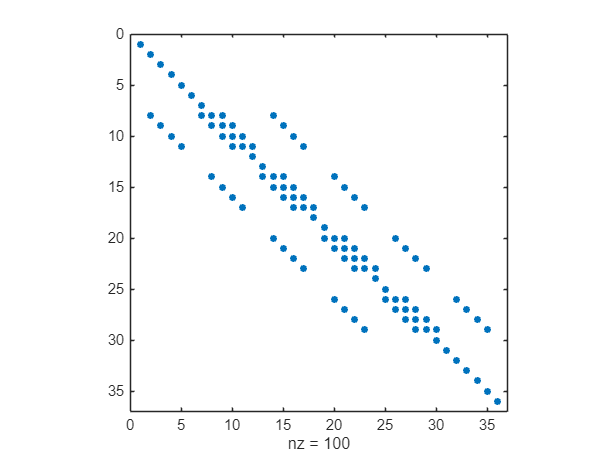

fTest = @(x,y) 0*x + 0*y + 4;
uTrue = @(x,y) x.^2 + y.^2;

Lx = 3; Ly = 3;
Nx = 5; Ny = 5;
nx = Nx+1; ny = Ny+1;
dx = Lx/Nx; dy = Ly/Ny;
x = (0:Nx)*dx; y = (0:Ny)*dy;
boundaryIndex = [1:nx, 1:nx :1+(ny-1)*nx, 1+(ny-1)*nx:nx*ny, nx:nx:nx*ny];

diagonals = [4*ones(nx*ny,1), -ones(nx*ny,4)];
A = spdiags(diagonals, [0 -1 1 -nx nx], nx*ny, nx*ny);
I = speye(nx*ny);
A(boundaryIndex,:) = I(boundaryIndex,:);
spy(A)

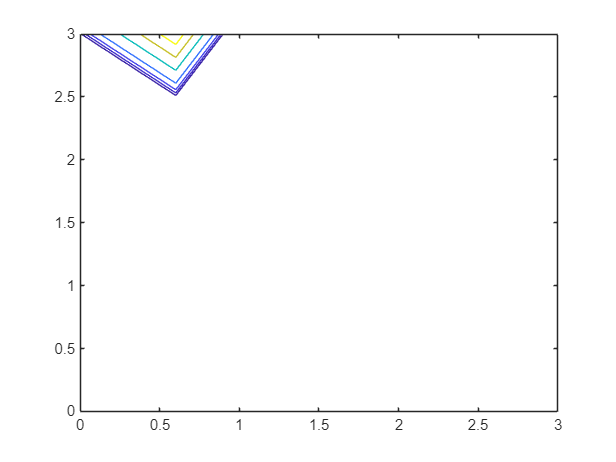


b = zeros(nx,ny);
b(:,1) = 0;
b(1,:) = 0;
b(:,ny) = 0;
b(nx,:) = 0;
b = reshape(b, nx*ny, 1);

Phi = A\b;
Phi = reshape(Phi, nx, ny);

[X,Y] = meshgrid(x,y);
v = [0.8 0.6 0.4 0.2 0.1 0.05 0.01];
contour(X,Y,Phi', v)

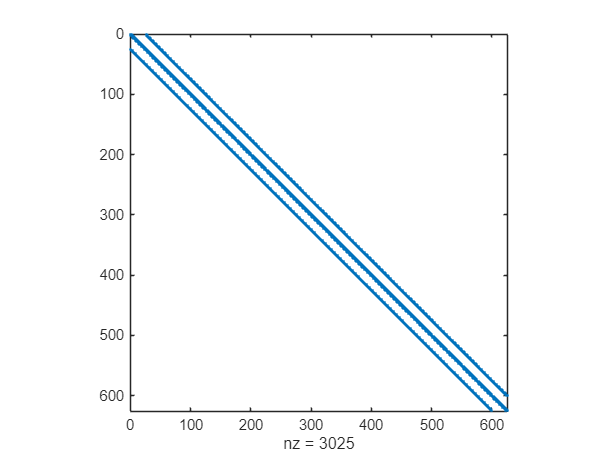

[X,Y] = meshgrid(x,x);
Z = fTest(X,Y);
% Z = peaks(X,Y);
F = h^2*Z(:);

I = eye(n);
c = [-2 1 zeros(1,n-2)];
D = toeplitz(c);
D = kron(D,I) + kron(I,D);
spy(D)

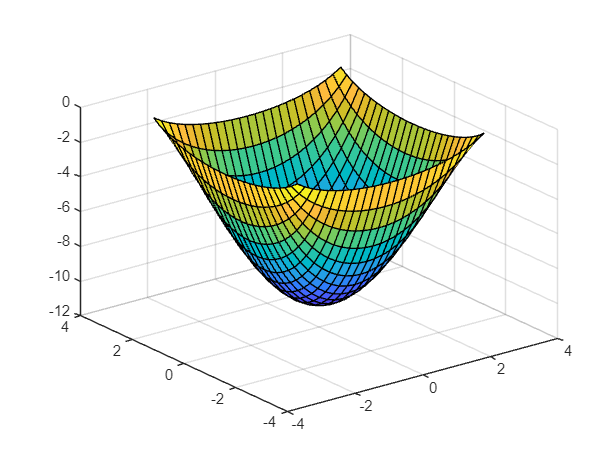


U = D \ F;
surf(X, Y, reshape(U, [n,n]))

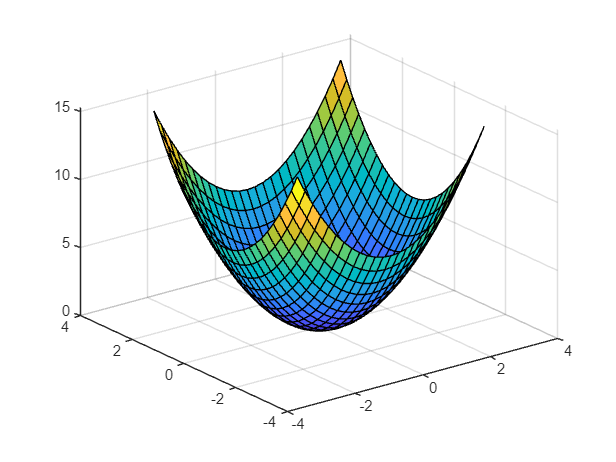

surf(X, Y, reshape(uTrue(X,Y), [n,n]))

% I = speye(n,n);
% E = sparse(2:n, 1:n-1, 1, n, n);
% D = E+E'-2*I;
% D = kron(D,I)+kron(I,D);
% 
% U = D \ F;
% surf(X, Y, reshape(U, [n,n]))

## (a)

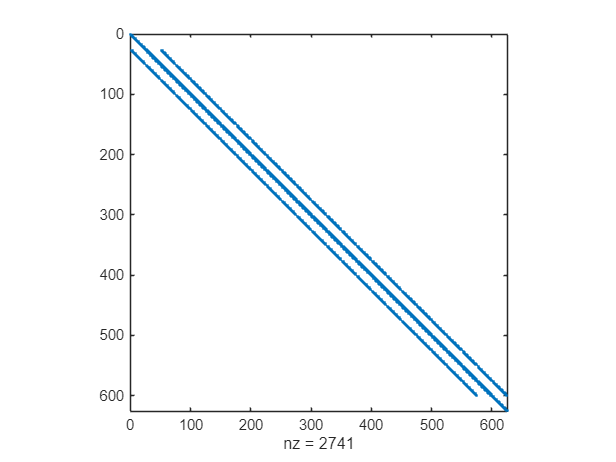

f = @(x,y) 0*x + 0*y + 4;
nx = 25;
ny = 25;
x = linspace(-3,3,nx);
y = linspace(-3,3,ny);
[X,Y] = meshgrid(x,y);
F = f(X,Y);

Ix = speye(nx); ex = ones(nx,1);
Iy = speye(ny); ey = ones(ny,1);
D2x = spdiags([ex -2*ex ex], -1:1, nx, nx);
D2y = spdiags([ey -2*ey ey], -1:1, ny, ny);
A = kron(Iy, D2x) + kron(D2y, Ix);

bdIndex = [1:nx, 1:nx :1+(ny-1)*nx, 1+(ny-1)*nx:nx*ny, nx:nx:nx*ny];
b = reshape(F, nx*ny, 1);
N = length(b);
I = speye(nx*ny);
A(bdIndex,:) = I(bdIndex,:);
spy(A)

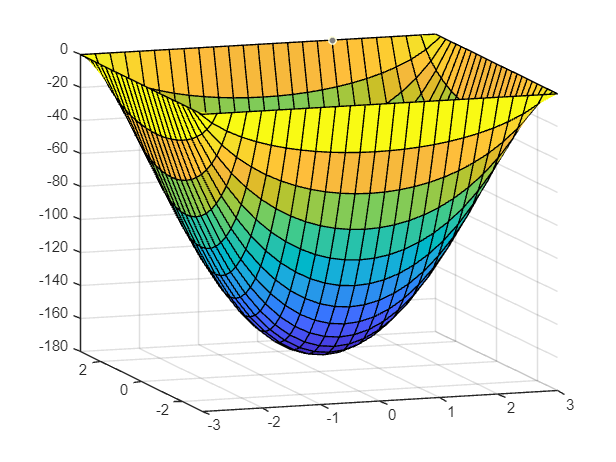

b(bdIndex) = 0;

u = A\b;
sol = reshape(u,nx,ny);
surf(X,Y,sol')

## (b)

## (c)

## (d)

function p = peaksSource(x,y)

[X,Y] = meshgrid(x,y);
p = peaks(X,Y);

end